# Lab - Numerical Integration 1: Newton-Cotes

**Topics: **trapezoidal rule, Simpson's 1/3, Simpson's 3/8, Hybrid Simpson's

clear, clc, format compact
format long

## Newton-Cotes methods

### Set up problem

Solve $\int_0^{0\ldotp 8} 0\ldotp 2+25x-200x^2 +675x^3 -900x^4 +400x^5 \;dx$

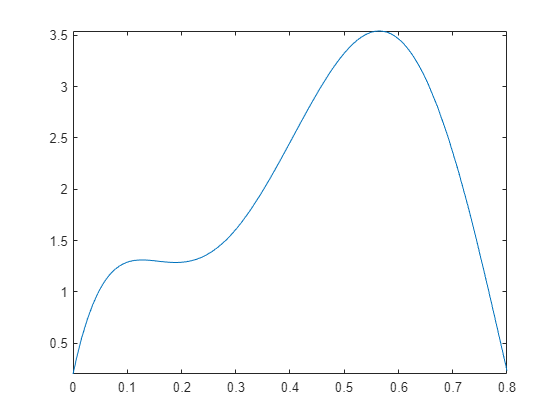

f = @(x) .2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5;
a = 0;
b = .8;
fplot(f,[a,b])

### Exact integral 

syms x
fx = .2 + 25*x - 200*x^2 + 675*x^3 - 900*x^4 + 400*x^5;
I_exact = double(int(fx, x, a, b))

I_exact =    1.640533333333333

### MPRTE calculation


$$\mathrm{MPRTE}=\left|\frac{\mathrm{true}-\mathrm{estimate}}{\mathrm{true}}\right|*100%$$


MPRTE = @(est) abs((I_exact-est)/I_exact)*100;

### Trapezoidal rule


$$I=\left(b-a\right)\left\lbrack \frac{f\left(a\right)+f\left(b\right)}{2}\right\rbrack$$


% single application
I_Trap_n1 = (b-a)/2*(f(a)+f(b))

I_Trap_n1 =    0.172800000000022

err_Trap_n1 = MPRTE(I_Trap_n1)

err_Trap_n1 =   89.466840052014234

% double application
n = 2;
h = (b-a)/n;
% I_Trap_n2 = h/2*(f(a)+f(a+h)) + h/2*(f(a+h)+f(b))    Inefficient
I_Trap_n2 = h/2*(f(a) + 2*f(a+h) + f(b))

I_Trap_n2 =    1.068800000000012

err_Trap_n2 = MPRTE(I_Trap_n2)

err_Trap_n2 =   34.850455136540262

% triple application
n = 3;
h = (b-a)/n;
I_Trap_n3 = h/2*(f(a) + 2*f(a+h) + 2*f(b-h) + f(b))

I_Trap_n3 =    1.369573662551444

err_Trap_n3 = MPRTE(I_Trap_n3)

err_Trap_n3 =   16.516559906243266

### Simpson's 1/3


$$I=\frac{h}{3}\left\lbrack f\left(x_0 \right)+4f\left(x_1 \right)+f\left(x_2 \right)\right\rbrack$$


% Single application
n = 2;
h = (b-a)/n;
I_Simp1_n1 = h/3*(f(a)+4*f(a+h)+f(b))

I_Simp1_n1 =    1.367466666666674

err_Simp1_n1 = MPRTE(I_Simp1_n1)

err_Simp1_n1 =   16.644993498048962

% Double application
n = 4;
h = (b-a)/n;
I_Simp1_n2 = h/3*(f(a) + 4*f(a+h) + 2*f(a+2*h) + 4*f(b-h) + f(b))

I_Simp1_n2 =    1.623466666666672

err_Simp1_n2 = MPRTE(I_Simp1_n2)

err_Simp1_n2 =    1.040312093627771

### Simpson's 3/8


$$I=\frac{3h}{8}\left\lbrack f\left(x_0 \right)+3f\left(x_1 \right)+3f\left(x_2 \right)+f\left(x_3 \right)\right\rbrack$$


% Single application
n = 3;
h = (b-a)/n;
I_Simp3_n1 = (3*h)/8*(f(a) + 3*f(a+h) + 3*f(b-h) + f(b))

I_Simp3_n1 =    1.519170370370372

err_Simp3_n1 = MPRTE(I_Simp3_n1)

err_Simp3_n1 =    7.397774888021889

% Double application
n = 6;
h = (b-a)/n;
I_Simp3_n2 = (3*h)/8*(f(a) + 3*f(a+h) + 3*f(a+(2*h)) + 2*f(a+(3*h)) + 3*f(b-(2*h)) + 3*f(b-h) + f(b))

I_Simp3_n2 =    1.632948148148148

err_Simp3_n2 = MPRTE(I_Simp3_n2)

err_Simp3_n2 =    0.462360930501397

### Hybrid Simpson's n=5

% Solution #1:
n = 5;
h = (b-a)/n;
I_hyb_1 = h/3*(f(a) + 4*f(a+h) + f(a+(2*h))) + (3*h)/8*(f(a+(2*h)) + 3*f(b-(2*h)) + 3*f(b-h) + f(b))

I_hyb_1 =    1.645077162666678

err_hyb_1 = MPRTE(I_hyb_1)

err_hyb_1 =    0.276972691808217

% Solution #2: 
n = 5;
h = (b-a)/n;
I_hyb_2 = (3*h)/8*(f(a) + 3*f(a+h) + 3*f(a+(2*h)) + f(b-(2*h))) + h/3*(f(b-(2*h)) + 4*f(b-h) + f(b))

I_hyb_2 =    1.611522730666679

err_hyb_2 = MPRTE(I_hyb_2)

err_hyb_2 =    1.768364109232005

I_Hyb = [I_hyb_1, I_hyb_2];
I_hyb_avg = mean(I_Hyb)

I_hyb_avg =    1.628299946666679

err_hyb_avg = MPRTE(I_hyb_avg)

err_hyb_avg =    0.745695708711894

### Table of results

headings = ["Method" "Integral" "MPRTE"];
methods = ["Exact", "Trap(1)", "Simp1/3(1)", ...
           "Trap(2)", "Simp3/8(1)", "Trap(3)", ...
           "Simp1/3(2)", "Hybrid(n=5)", "Simp3/8(2)"];
integrals = [I_exact, I_Trap_n1, I_Simp1_n1, I_Trap_n2, I_Simp3_n1, I_Trap_n3, I_Simp1_n2, I_hyb_avg, I_Simp3_n2];


for j = 1:length(methods)
    if j == 1
        fprintf(['%-11s %-10s %-6s\n' ...
                 '----------- ---------- ------\n'], headings)
    end
    fprintf('%-11s %10.8f %5.2f%%\n', methods(j), integrals(j), MPRTE(integrals(j)))
end

Method      Integral   MPRTE 
----------- ---------- ------


Exact       1.64053333  0.00%
Trap(1)     0.17280000 89.47%
Simp1/3(1)  1.36746667 16.64%
Trap(2)     1.06880000 34.85%
Simp3/8(1)  1.51917037  7.40%
Trap(3)     1.36957366 16.52%
Simp1/3(2)  1.62346667  1.04%
Hybrid(n=5) 1.62829995  0.75%
Simp3/8(2)  1.63294815  0.46%
